**Below we recover the mean-field dynamics of non-interacting particles undergoing constant drift and spatial periodic diffusion at frequency **$\omega$**. For **$\omega=1$**, we recover the full system, whereas for **$\omega=20$** we recover the homogenized system. **

filePath = matlab.desktop.editor.getActiveFilename;
cd(filePath(1:strfind(filePath,'livescripts/local2D_livescript')-1))
addpath(genpath(filePath(1:strfind(filePath,'livescripts/local2D_livescript')-1)));
set(0,'DefaultFigurePosition',[1200 800 580 406])
warning('off','MATLAB:dispatcher:UnresolvedFunctionHandle')
clear;close all;clc;

omega=20;

if omega==1
    load('datasets/local2D_omega1.mat')
elseif omega==20
    load('datasets/local2D_omega20.mat')
end

## Compute approximate particle distribution $U$ from particles Xscell

%%% choose experiments from Xscell to use in regression 
exps = 1;

%%% choose number of particles to use from each experiment
NN = 2^15;

%%% choose histogram grid resolution
numx = 200 + 1;
numsdv = inf;
custdom = [];
coarsen_data = [[0 1 1];[0 1 1];[0 2 1]];
scoord = 0;

%%% set extrinsic noise level
Xsnz = [0 1];

%%% compute histogram
get_particle_distrib;

ET_load_data = 1.2616 


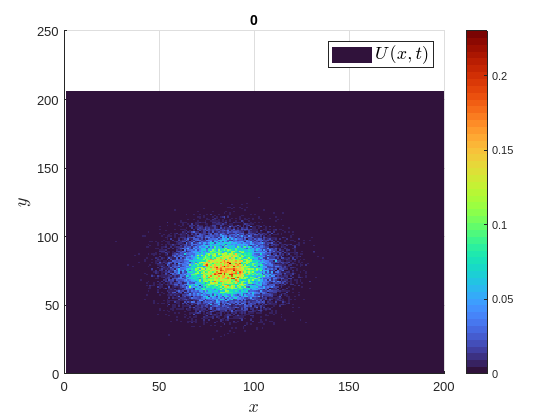

plotgap=inf;
plot_distrib;

## Choose model library

%%% local autonomous operators
max_dx = 0;
max_dt = 0;
polys = 0;
trigs = [];
use_all_dt = 0;
use_cross_dx = 0;
custom_add = [];
custom_remove = {};
toggle_comb = 1;

%%% local non-autonomous operators
driftpolys=[0]; drifttrigs=[1:5];
diffpolys=[0]; difftrigs=[1:5]; crossdrift=0;

%%% non-local operators
dim = size(Xscell{1},2)+1;
convargs = {{'dimx',dim-1,'utagin',1,'utagout',1,'psitags',1,'Mon',[1:7],'Sing',[],'Exp',[],'Singeps',[0.01],'svdtol',[1e-4]}};

set_library;

ET_build_lib = 0.2249 


## Set weak discretization

phi_class = {1,1};
sm_x = 3;
sm_t = 3;

% %%% manually set test function params
% p_x = 5; mxs = 31;
% tau_x = []; k_x = []; tauhat_x = []; 
% p_t = 3; mts = 16;
% tau_t = []; k_t = []; tauhat_t = [];

%% set test function params using cornerpoint
p_x = 5;tauhat_x = 1;
tau_x = [];k_x = [];mxs = 1;
p_t = 3;tauhat_t = 2;
tau_t = [];k_t = [];mts = 1;

%%% rescale coordinates and/or use approx. variance for improved conditioning
scales = 2;
covtol = 0; 

%%% trim rows with low particle density
trim_tags = [1 zeros(1,dim-1) 0]; 
trim_fcn = {@(col) max(col/max(abs(col)),eps)};
inds_keep_fcn = @(col) log10(col)>-inf;

set_discretization;

ET_setdisc = 0.8802 


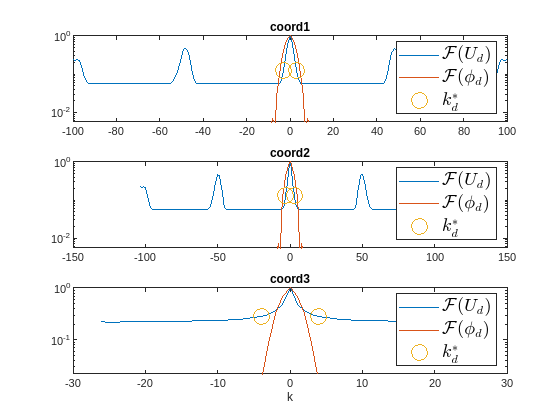


toggle_plot_fft = 1;
plot_Ufft;

## Build linear systems

build_Gb;

ET_build_Gb = 13.3966 


## MSTLSQP

lambda = 10.^(linspace(-4, 0, 100));
gamma_tol = Inf;
alpha = 0.5;
maxits = Inf;
sparsity_scale = 0;
excl_tags ={'([x.^0.*y.^0.*t.^0]u^1)_{lap}'};
excl_tols = 0;
tol = 10^-8; 
maxQPits = 100; 
dispQP = 'off';
meth = 'STLSQP';

sparsereg_script;

ET_solve_sparse_reg = 3.2378 


## Display results

print_loc = 1;
get_results;


Recovered PDE: u^{1}_{t} = -1.01709([x.^0.*y.^0.*t.^0]u^1)_{x} + -0.989376([x.^0.*y.^0.*t.^0]u^1)_{y} + 0.605778([x.^0.*y.^0.*t.^0]u^1)_{lap}
Relative Res: ||b-G*W||_2/||b||_2 = 2.72e-02
Max Weight Error: max|W-W_{true}| = 2.16e-02
TP Score = 1.00
      
polys = 1 
trigs =  
Max derivs [t x] = 1 2 
[m_x m_t] = 38 12 
[s_x s_t] = 12 4 
[p_x p_t] = 5 3 
 scales = 1.00e+00 1.08e+00 1.08e+00 2.08e+00 
      
Total particles = 32768 
Size of dataset = 200 206 51 
Size G = 847 85 
Cond G = 3.55e+07
[lambda_hat gamma] = 2.656e-02 0.000e+00 
[sigma_NR sigma] = 0.000e+00 
      
STLS its = 5 
 
ET_load_data = 1.2616 
ET_build_lib = 0.2249 
ET_setdisc = 0.8802 
ET_build_Gb = 13.3966 
ET_solve_sparse_reg = 3.2378 
Elapsed time WSINDy = 19.0011 


## Display loss

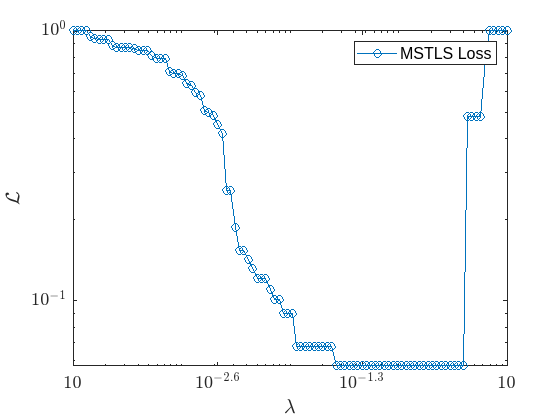

toggle_plot_loss = 1;
plot_loss;

## Display drift/diffusion

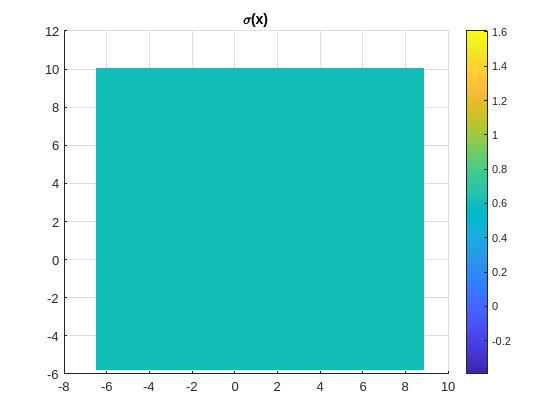

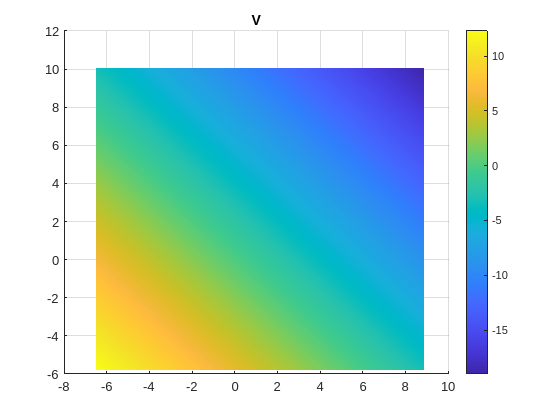

toggle_plot_drift = 1;
plot_driftdiff;

## Display interaction force

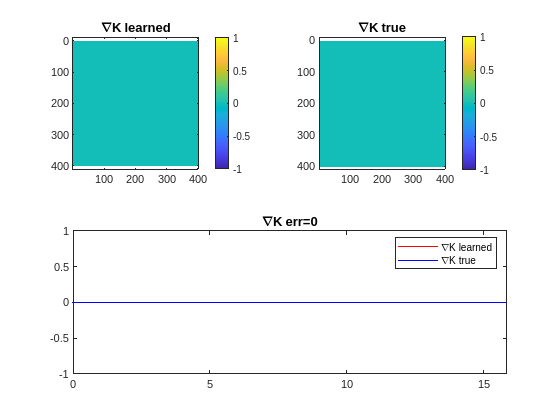

toggle_plot_IPforce = 1;
plot_K